# Exercicio 1

## Exercicio 1 - Criar sinais

Ta  = 0.01; % Período de amostragem

## a)

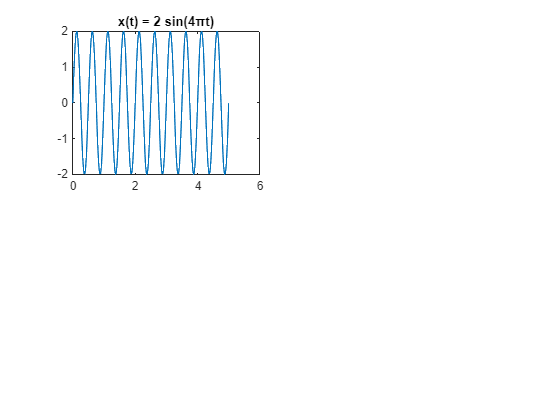

t_a = 0:Ta:5;
x = 2 * sin(4 * pi * t_a);

figure  

subplot(2,2,1)
plot(t_a, x)
title('x(t) = 2 sin(4πt)');

## b)

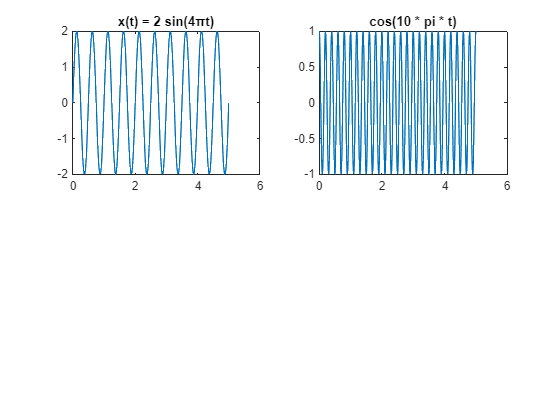

y = cos(10 * pi * t_a);

subplot(2,2,2);
plot(t_a,y)
title('cos(10 * pi * t)')

## c)

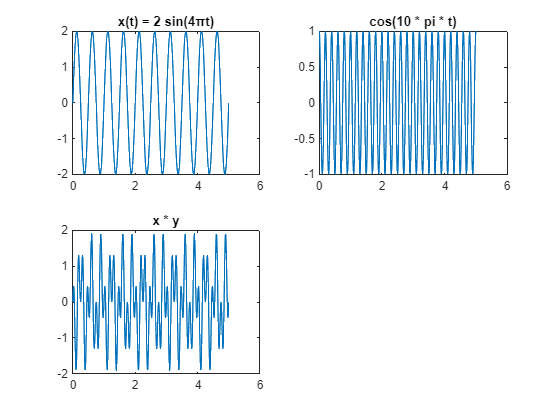

z = x .* y;

subplot(2,2,3)
plot(t_a,z)
title('x * y')

## d)

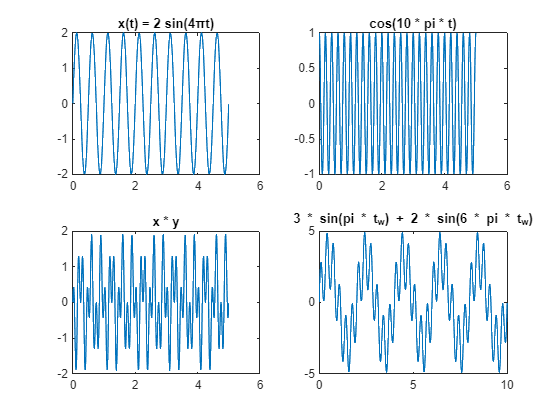

t_w = 0:Ta:10;
w = 3 * sin(pi * t_w) + 2 * sin(6 * pi * t_w);

subplot(2,2,4);
plot(t_w,w)
title('3 * sin(pi * t_w) + 2 * sin(6 * pi * t_w)')

## e)

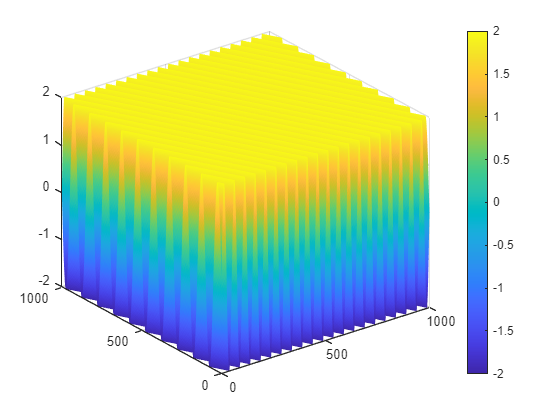

t1 = 0:Ta:10;
t2 = 0:Ta:10;

%% Isto forma uma grelha no espaço 2D, onde cada entrada (i, j) 
% em XX e YY representa um ponto (x, y) a partir das combinações de valores em t1 e t2.
[XX, YY] = meshgrid(t1,t2);

figure
q=2 * sin(2* pi *(2 * XX + YY));
surf(q,EdgeColor="none")
colorbar

## Exercicio 2 - Criar sinais

Ta2  = 0.1; % Período de amostragem

## a)

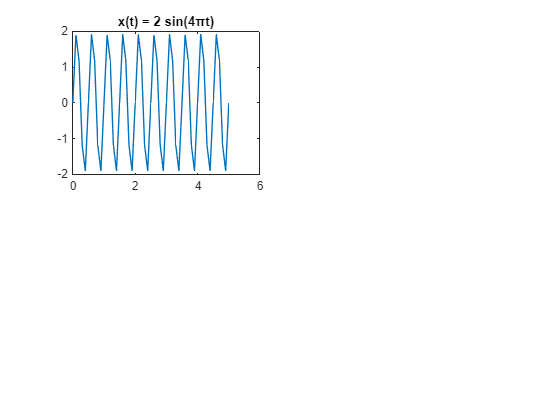

t_a = 0:Ta2:5;
x2 = 2 * sin(4 * pi * t_a);

figure  

subplot(2,2,1)
plot(t_a, x2)
title('x(t) = 2 sin(4πt)');

## b)

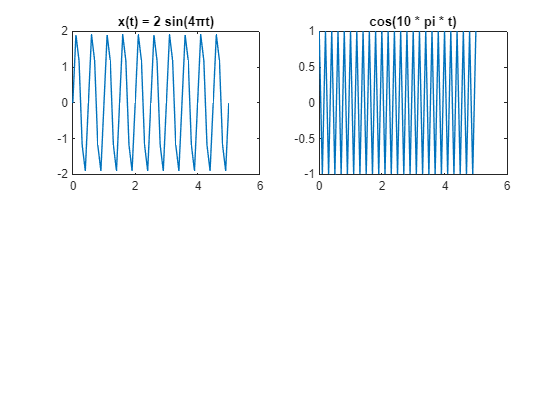

y2 = cos(10 * pi * t_a);

subplot(2,2,2);
plot(t_a,y2)
title('cos(10 * pi * t)')

## c)

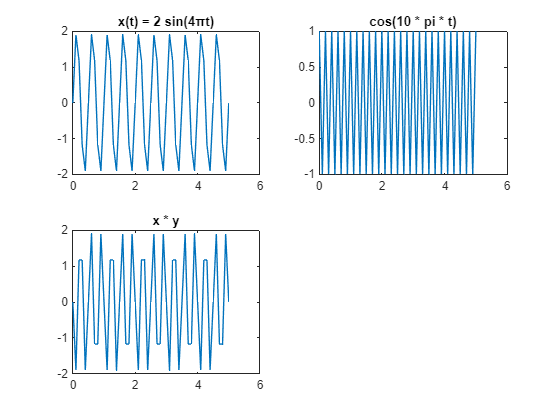

z2 = x2 .* y2;

subplot(2,2,3)
plot(t_a,z2)
title('x * y')

## d)

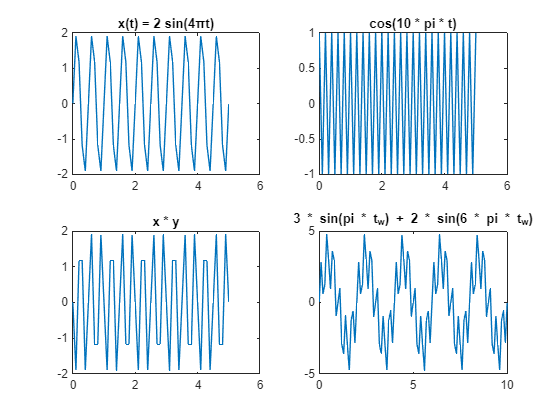

t_w = 0:Ta2:10;
w2 = 3 * sin(pi * t_w) + 2 * sin(6 * pi * t_w);

subplot(2,2,4);
plot(t_w,w2)
title('3 * sin(pi * t_w) + 2 * sin(6 * pi * t_w)')

## e)

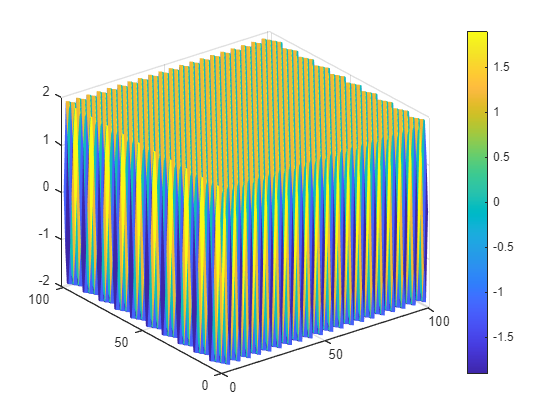

t1 = 0:Ta2:10;
t2 = 0:Ta2:10;

%% Isto forma uma grelha no espaço 2D, onde cada entrada (i, j) 
% em XX e YY representa um ponto (x, y) a partir das combinações de valores em t1 e t2.
[XX, YY] = meshgrid(t1,t2);

figure
q2=2 * sin(2* pi *(2 * XX + YY));
surf(q2,EdgeColor="none")
colorbar

## Exercicio 3

𝑥(𝑡) – traço contínuo e fino, de cor vermelha 

𝑦(𝑡) – traço grosso a tracejado, de cor azul

 𝑧(𝑡) – traço contínuo e fino, de cor verde, com pontos em cada amostra

 𝑤(𝑡) – traço contínuo e grosso, de cor amarela 

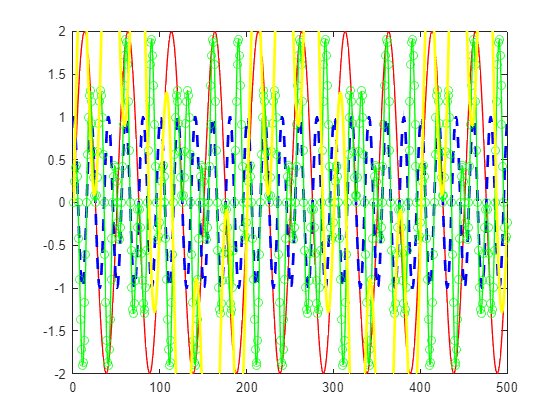

plot(x,'r')
axis([0 500 -2 2]); % Defina os limites dos eixos
hold on
plot(y,'b--','LineWidth',2.0)
plot(z,'g-o')
plot(w,'y','LineWidth',2.0)

## Exercicio 4

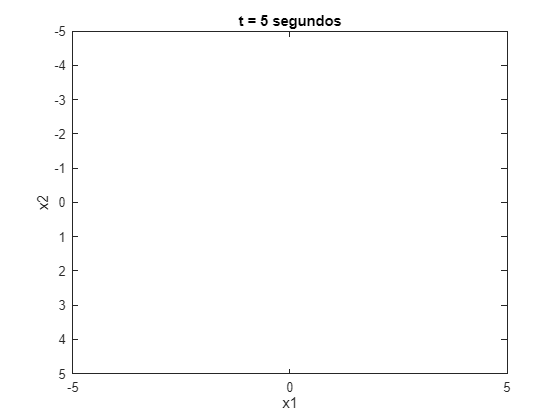

ta = 0.01;

x1 = -5:ta:5;
x2 = -5:ta:5;

Ta = 1/25;
t = 0:Ta:5;

[XX, YY]=meshgrid(x1,x2);
figure

% Loop através das amostras de tempo
for k = 1:length(t)
    r = 2*sin(2*pi*sqrt(XX.^2+YY.^2)-2*pi*t(k));
    
    % Plote a imagem 2D
    imagesc(x1, x2, r); % Plote a imagem usando imagesc
    axis([-5 5 -5 5]); % Defina os limites dos eixos
    
    xlabel('x1');
    ylabel('x2');
    title(['t = ', num2str(t(k)), ' segundos']);
    
    % Aguardar um curto período de tempo para criar a sensação de animação
    pause(0.1); 
    
    % Limpar o subplot para a próxima iteração
    cla;

end